% updated: Aug 21, 2019
% written by minhae kwon
% minhae.kwon@rice.edu
% Midbrain Dopamine Neurons Signal Belief in Choice Accuracy during a Perceptual Decision
% Armin Lak, Kensaku Nomoto, Mehdi Keramati, Masamichi Sakagami, Adam Kepecs
% 2017, Current Biology 27, 821–832


% there are four states: fixation cue, motion stimulus, feedback, end(=
% initial)

%%%%%%%%%%%%%%%%%%%%%%%%%
% Define constant here:
STATE_SIZE = 21; % 21 stimulus(coherence level)
STATE_SET = 1:1:STATE_SIZE; % states: 21 levels: 
COHERENCE_SET = (STATE_SET -11)*5;% -50, -45, ..., 45, 50 (coherence level [%]) 
STATE_SET = STATE_SET'; % column vector
ACTION_SIZE = 2; % only two action. Left or Right

OBS_STD = 0.01; % observation (hat s) standard deviation
BEL_STD = 5; 
REWARD_BIG = 0.38; % reward = juice
REWARD_SMALL = 0.16;
LR = 0.1; % Learning rate
TOT_TRIAL = 10000;

epsilon = 1;
%%%%%%%%%%%%%%%%%%%%%%%%%

% initialization
q_table = rand(STATE_SIZE, ACTION_SIZE); % row: state index, column 1: left, column 2: right
q_table_log = zeros(STATE_SIZE, ACTION_SIZE, TOT_TRIAL);
true_s_log = zeros(1, TOT_TRIAL);
obs_s_log = zeros(1, TOT_TRIAL);
bel_s_log = zeros(STATE_SIZE, TOT_TRIAL);
q_log = zeros(2, TOT_TRIAL);
a_log = zeros(1, TOT_TRIAL);
v_fc_log = zeros(1, TOT_TRIAL);
delta_m_log = zeros(1, TOT_TRIAL);
delta_fb_log = zeros(1, TOT_TRIAL);
hit_log = zeros(1, TOT_TRIAL);
true_a_log = zeros(1, TOT_TRIAL);
maxq_log = zeros(1, TOT_TRIAL);

% unbalanced reward
REWARD = [REWARD_SMALL, REWARD_BIG]; %Left, Right



for t = 1: TOT_TRIAL
    
    
    
    
    % experimentalist gives a stimulus based on uniform distribution
    true_s = randi(STATE_SIZE); 
    
    % observation of monkey : hat s
    obs_s = OBS_STD * randn(1)+ true_s; % just one sample form Gaussian distribution
    obs_s = min(max(1, obs_s),STATE_SIZE); % make sure it's in [1,21]
    
    % monkey's belief p(sm|\hat Sm)
    gm = gmdistribution(obs_s,BEL_STD);% Gaussian distribution
    bel_s = pdf(gm,STATE_SET);
    bel_s = bel_s/ sum(bel_s); % make sure total sum is 1 --> since it's probability
        
    
    % fixation cue
    % assume uniform distribution for belief.
    v_fc = sum(q_table(:))/STATE_SIZE/2; 
    
        
    % motion stimulus
    q_l = sum(bel_s .* q_table(:,1));
    q_r = sum(bel_s .* q_table(:,2));
    
    q = max([q_l, q_r]);  % max Q value, index( which is action) 
    
    % epsilon greedy
    epsilon = 0; %max(epsilon - 1/(TOT_TRIAL*0.2),0);  
    
    if rand > epsilon        
        a = find([q_l, q_r]== q);
        
        %If the largest element occurs more than once, then it randomly selects the action with uniform distribuiton.
        if size(a,2) > 1
            idx = randi(size(a,2));
            a = a(idx);
        end
        
    else % for exploration
        a = randi(ACTION_SIZE);
        
    end
    
    delta_m = q - v_fc; % prediction error
    
    % feed-back    
    true_coherence = COHERENCE_SET(true_s); %-(STATE_SIZE+1)/2;
    if true_coherence == 0 % zero coherence : random true action
        ture_a = randi(ACTION_SIZE);                
    else
        true_a = (true_coherence>0)+1;        
    end
    hit = (true_a == a);
    
    
    if hit == 1
        reward = REWARD(a);
    else 
        reward = 0;
    end
    
    delta_fb = reward - q;
    q_table(:,a) = q_table(:,a) + LR *delta_fb .* bel_s; 
    
    % log all data
    q_table_log(:,:,t) = q_table; 
    true_s_log(t)= true_s;    
    obs_s_log(t) = obs_s;
    bel_s_log(:,t) = bel_s;
    q_log(:,t)= [q_l, q_r];
    
    a_log(t) = a;
    v_fc_log(t)= v_fc;
    delta_m_log(t) = delta_m;
    delta_fb_log(t)= delta_fb;  
    hit_log(t) = hit;
    true_a_log(t) = true_a;
    maxq_log(t) = q;

end 



##  Plot 

EXPLOIT_TW = 1000:TOT_TRIAL;
correct_count = 0;
error_count = 0;
for j = EXPLOIT_TW % check only well-trained monkey (converged q value)
    if hit_log(j)>0
        correct_count = correct_count+ 1;
        true_s_correct(correct_count) = true_s_log(j);
        delta_m_correct(correct_count) = delta_m_log(j);
        delta_fb_correct(correct_count) = delta_fb_log(j);
        hit_correcct(correct_count) = 1;
        
    else 
        error_count = error_count + 1;
        true_s_error(error_count) = true_s_log(j);
        delta_m_error(error_count) = delta_m_log(j);
        delta_fb_error(error_count) = delta_fb_log(j);
        hit_error(error_count) = 1;
    end
end

varNames = {'true_s', 'delta_m', 'delta_fb','hit'};
T_correct = table(true_s_correct', delta_m_correct', delta_fb_correct',hit_correcct','VariableNames',varNames);
T_error = table(true_s_error', delta_m_error', delta_fb_error',hit_error','VariableNames',varNames);


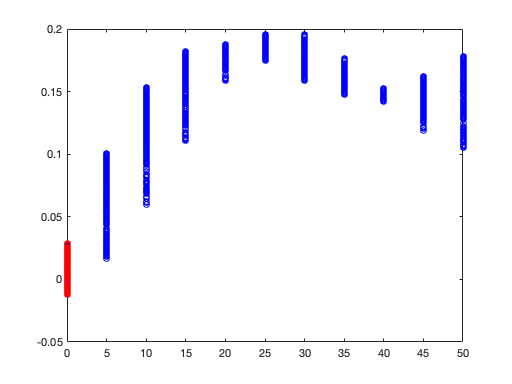



POSITIVE_RANGE = 11:21;
figure;
for s = POSITIVE_RANGE % only positive coherences
    temp_correct = T_correct(T_correct.true_s == s,:);
    temp_error = T_error(T_error.true_s == s,:);
    mean_correct(s) = mean(temp_correct.delta_m);
    
    
    plot(COHERENCE_SET(s),temp_correct.delta_m, 'bo');
    hold on;
    
    if size(temp_error,1) >0
        mean_error(s) = mean(temp_error.delta_m);
        plot(COHERENCE_SET(s),temp_error.delta_m, 'ro');
        hold on;        
    end
   
end


plot(COHERENCE_SET(POSITIVE_RANGE), mean_correct(POSITIVE_RANGE), '-b*');

다음 사용 중 오류가 발생함: plot
벡터들의 길이는 같아야 합니다.

hold on;
plot(COHERENCE_SET(POSITIVE_RANGE), mean_error(POSITIVE_RANGE), '-r*');

xlabel('coherence level[%]');
ylabel('delta_m');
title('Stimulus');




figure;
for s = POSITIVE_RANGE % only positive coherences
    temp_correct = T_correct(T_correct.true_s == s,:);
    temp_error = T_error(T_error.true_s == s,:);
    mean_correct(s) = mean(temp_correct.delta_fb);
    
    
    plot(COHERENCE_SET(s),temp_correct.delta_fb, 'bo');
    hold on;
    
    if size(temp_error,1) >0
        mean_error(s) = mean(temp_error.delta_fb);
        plot(COHERENCE_SET(s),temp_error.delta_fb, 'ro');
        hold on;
        
    end
   
end

plot(COHERENCE_SET(POSITIVE_RANGE), mean_correct(POSITIVE_RANGE), '-b*');
hold on;
plot(COHERENCE_SET(POSITIVE_RANGE), mean_error(POSITIVE_RANGE), '-r*');

xlabel('coherence level[%]')
ylabel('delta_{fb}')
title('feedback')


hit_rate = zeros(1,STATE_SIZE);

for s = STATE_SET'
    temp_correct = T_correct(T_correct.true_s == s,:);
    temp_error = T_error(T_error.true_s == s,:);
    hit_rate(s) = sum(temp_correct.hit)/(sum(temp_correct.hit)+sum(temp_error.hit));
end


figure;
plot(COHERENCE_SET(POSITIVE_RANGE), hit_rate(POSITIVE_RANGE), '-b*');
hold on;
plot(COHERENCE_SET(POSITIVE_RANGE), hit_rate(11:-1:1), '-ro');
xlabel('coherence level [%]')
legend('High Reward', 'Low Reward');
ylabel('Accuracy');



    



figure;
plot((true_s_log-11)*5, '*');
axis([0, TOT_TRIAL, -50, 50]);
xlabel('trial');
ylabel('coherence level [%]')


tw = 1:50; %time window

figure;
imagesc(bel_s_log(:,tw))
colorbar;
hold on;
plot(true_s_log(tw),'-r*')



figure;
plot(v_fc_log);
xlabel('trial');
ylabel('v_fc');
title('fixation cue');


figure;
plot(delta_m_log);
xlabel('trial');
ylabel('\delta_m');
title('stimulation');

figure;
for j = EXPLOIT_TW
    if hit_log(j) == 1
       plot(COHERENCE_SET(true_s_log(j)), delta_m_log(j),'b*'); 
       hold on;
    else 
       plot(COHERENCE_SET(true_s_log(j)), delta_m_log(j),'ro'); 
       hold on;
    end
end
xlabel('coherence level');
ylabel('\delta_m')


figure;
plot(COHERENCE_SET(true_s_log(EXPLOIT_TW)), delta_fb_log(EXPLOIT_TW),'*')
xlabel('coherence level');
ylabel('\delta_{fb}')





figure;
plot(delta_fb_log);
xlabel('trial');
ylabel('\delta_{fb}')


figure;
%plot(a_log);
hist(a_log);


h = histogram2(COHERENCE_SET(true_s_log(EXPLOIT_TW)), hit_log(EXPLOIT_TW),[21,2]);
xlabel('Coherence level [%]');
ylabel('hit');
zlabel('number of trial');





% exploit_tw = TOT_TRIAL-round(TOT_TRIAL/2):TOT_TRIAL;
% figure;
% plot(COHERENCE_SET(true_s_log(exploit_tw)),hit_log(exploit_tw),'*');



figure;
plot(maxq_log);

hit_ratio = zeros(1,TOT_TRIAL);
for j = 1: TOT_TRIAL
    hit_ratio(j) = sum(hit_log(1:j))/j;
end


figure;
plot(hit_ratio);
xlabel('trial');
ylabel('hit ratio');